# PI Controller Design for the Opulent Voice Costas Loop

*Version 2.0 Abraxas3d 18 November 2024*

*Version 3.0 ORI 20 November 2024*

*Version 4.0 ORI 21 November 2024*

Opulent Voice (OPV) is an open-source high-bitrate digital voice communication protocol designed to deliver high-quality audio over radio frequencies. OPV uses advanced modulation techniques and a 16 kbps OPUS voice encoder and decoder (CODEC) to achieve excellent sound quality, providing a rich and opulent audio experience compared to standard voice  protocols.

The OPV protocol is open-source, meaning developers can freely access and modify the code for use in radio systems. The implementation details discussed here are for the PLUTO, a low-cost education-focused software defined radio (SDR) from Analog Devices. The PLUTO implementation's repository can be found at https://github.com/openresearchinstitute/pluto_msk

In order to help receive the minimum shift key (MSK) signal, a Costas Loop has been implemented in the open source hardware description language (HDL) receiver design. A Costas Loop is a phase-locked loop (PLL) based circuit which is used for carrier frequency recovery. A PLL adjusts the phase of a locally generated signal to match the phase of an input signal.

We know where our signal is supposed to be, but because each radio is slightly different, and because there may be Doppler on top of that, there will be frequency errors at the receiver. A Costas Loop corrects and tracks the signal we want to receive by generating a local signal and then matching that local signal's frequency and phase to the received signal. Once we have matched the frequency of the received signal, or "synchronized" our signal, we multiply the locally generated signal by the received signal to start the process of recovering the modulated information that was transmitted to us. If we didn't know the frequency and phase of our received signal, then the multiplications won't work well, if at all. 

Inside the Costas Loop is a proportional and integral control structure (PI Controller). The implementation is a stand-alone submodule, and that work can be found here [https://github.com/OpenResearchInstitute/pi_controller.](https://github.com/OpenResearchInstitute/pi_controller.)

The defining characteristics of a PI Controller are two coefficients. There's a proportional coefficient (Kp) and an integral coefficient (Ki). The PI Controller is defined by a transfer function, which tells us how it responds to input data. The PI Controller input is the error between the phase of what we received over the air and the phase of our locally generated signal. The PI Controller output is a voltage representing the necessary frequency adjustment required at the locally generated signal, which for OPV is a numerically controlled oscillator (NCO). The goal is for that NCO to have the same phase as the incoming signal.

The NCO generates the signals that we use to "break down" the received signal into modulated data, so having the right frequency and phase is crucial. Our job is to determine the value of the two coefficients Kp and Ki, so that the PI Controller can be configured to respond to the input. If the coefficients are too high or too low, then the controller won't be able to deal with the error messages. 

Think of the process of synchronizing to the received signal as like merging onto a freeway. If your vehicle is a rocket and can only accelerate at the speed of sound, then you are going to have a very hard time matching the speed of the cars on the road. If your vehicle can only accelerate at 0.01 kilometers per hour, you will not be merging anytime soon. The wrong coefficients for the PI Controller can be just as hazardous to digital signal processing as the wrong type of vehicle is on a freeway. With the right coefficients, we have a vehicle that is capable of accelerating (or decelerating) to join traffic with minimal difficulty. It has enough horsepower and acceleration (or braking!) to match the speeds of all the other cars on the road by the end of the on-ramp. 

We have three components. First, the NCO, which generates the local reference signals which need to closely match what's in our received signal. Second, a phase error detector, which calculates the difference in phase between the messy real-world received signal and the reference signal currently being generated by the NCO. Third, a circuit (the PI Controller) that translates that phase difference into instructions for the NCO, so that the NCO can adjust its phase. 

The PI controller calculates the corrections for the NCO based on both the current error and the accumulated error over time. The current error is multiplied by the proportional term Kp. Accumulated error is multiplied by the integral term Ki. A PI Controller can react to changes in the error quickly while also providing accuracy over time. 

There are other types of controllers. For example, a PID Controller has an additional derivative term. This extra term attempts to "predict the future" by responding to the rate of change of the input signal. A PD Controller has proportional and derivative terms, but doesn't have the intergral term. There are trade offs to all the different types of controllers. The PI Controller has the aspects that we want at an acceptable level of complexity and latency. 

Let's look at a generic example of a continuous time PI Controller. We visualize our controller by using a Bode Diagram, which plots the magnitude of the output signal vs. the frequency of the input signal. We will also plot the phase of the output signal vs. the frequency of the input signal. Looking at the Bode Diagram, we can see that we have created a low pass filter. 

In a Costas Loop, this low-pass filter function removes high-frequency components from the signal produced by the phase error detector. We only want the filtered error signal to pass through. This error signal is used to adjust the NCO to match the phase of the received signal. We want the Costas Loop to react only to the phase difference between the received signal and the local reference signal, and not react to unwanted noise and interference. Our PI Controller provides this service to the Costas Loop.

We define Kp = 1 and Ki = 0.5. There are at least two ways to define the transfer function. We can use either pid() or tf(). 

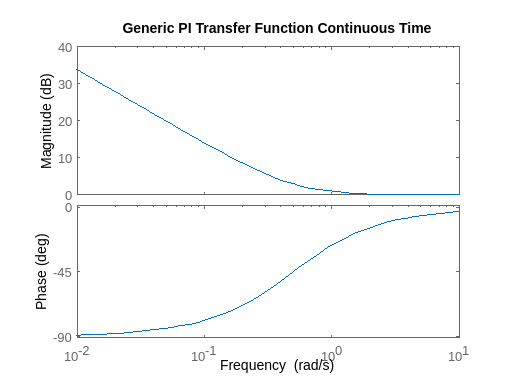

Kp = 1;
Ki = 0.5;
pi_tf = pid(Kp,Ki,0); %produces transfer function in parallel form
pi_tf2 = tf([Kp, Ki], [1, 0]);

bode(pi_tf);
title('Generic PI Transfer Function Continuous Time')

Next, let's set up and draw a Bode Diagram and Frequency Plot for our discrete time PI Controller running at our sample rate. Now we are in the environment of our particular implementation on the PLUTO SDR, so we need to define the signals we will be using to calculate our specific Kp and Ki. 

Our hardware is running at a clock rate of 61.44 MHz. We discard 24 out of 25 samples to reduce the rate from the hardware clock down to a sample rate (Fs) of 2,457,600 Hz. Opulent Voice bitrate is 54,200 Hz. 433,600 Hz is our intermediate frequency (IF). And, our minimum shift keying (MSK) higher frequency (F2) is IF + bitrate/4.

MSK uses two frequencies to transmit data very similarly to the way frequency shift keying (FSK) works. However, unlike the vast majority of the implementations of FSK, MSK uses two very carefully selected frequencies that have continuous phase. When switching from the lower frequency F1 to the higher frequency F2 and vice versa there are no jumps or gaps. This creates a constant envelope signal. That's not the only advantage of MSK, but it's a big one. The intermediate frequency is an integer multiple of the bitrate divided by four. We use an intermediate frequency to get the signals of interest away from DC. We need to select an IF that is an integer multiple of the bitrate/4 in order to preserve the mathematical relationship between F1 and F2. With the right IF (or carrier frequency) then the signal has continuous phase and no discontinuities at the symbol boundaries. 

discard_ratio = 25; %we discard N-1 and keep the Nth
Fs = 61.44e6/discard_ratio; %operating sampling rate
bitrate = 54200; %bitrate of our MSK signal
Fc = (bitrate/4)*32; %this is the IF
F2 = Fc + bitrate/4; %this is the upper frequency of the MSK signal

A Loop Bandwidth (LB) is the range of frequencies in the signal of interest that our control system can respond to. Outside of a loop bandwidth, the control loop may simply not be able to "pull in" the signal or produce any meaningful output. 

The recommendation for PI Controllers is to use a loop bandwidth in a range defined by no larger than the target frequency/20 and no smaller than target frequency/200. The larger the loop bandwidth, the wider range of frequencies that we can respond to, and the faster we can respond to them, but the more noise we allow in. The smaller the loop bandwidth, the smaller the range that we can respond to and the slower the response time, but we reduce the noise and increase performance within the loop. A large loop bandwidth is like a pair of binoculars or a spotting scope. A small loop bandwidth is a powerful telescope on a slow motorized mount. Using both together in the same observatory sessions can make finding and following "faint fuzzies" in the night sky much easier and more efficient. 

We can start out with a large loop bandwidth. We can get fancy later and add the ability to dynamically adjust the loop bandwidth after we acquire our signal, if it turns out that we need or want to do this. So, we define the variable Bn to be the fraction of the target frequency or rate that we want to be our loop bandwidth. Our target frequency is the higher of the two MSK tones, F2. Our loop bandwidth is Bn multiplied by F2.

**We write down Kv, the gain of the phase accumulator in the NCO, as Fs. The NCO is running at Fs, so (M/2^32) or (phase increment normalized by the register size) is scaled by Fs to produce output F2.**

When we talk about the gain of an accumulator, this is similar to the gain of a physical or mechanical accumulator. In hydraulic systems, an accumulator stores energy over time. This allows the system to maintain pressure, absorb fluctuations of pressure, and to provide output pressure through valves when work is needed. 

In a digital signal processing system, an accumulator stores mathematical results over time. The numbers add up every clock cycle. The phase increment can be thought of as the step size that the output sinusoidal signal is forced to make every clock cycle. A large phase increment per clock cycle is a large gain and a faster output frequency. A small phase increment per clock cycle is a small gain and a smaller output frequency. Completely filling the accumulator represents a full 360 degrees (or 2*pi radians) of an output sinusoid waveform. A value of 0 in the accumulator represents 0 degrees.The value in the accumulator is used as a lookup table to get discrete amplitude values of a sinuoidal waveform. We have 32 bit accumulators, so 2^32 represents 360 degrees. When our accumulator, operating essentially as a counter, rolls over from FFFF FFFF to 0000 0000 then we have output a full period of the waveform and we can start over again at 0 degrees.  

If we are clocking our accumulator at Fs Hz, and if each value added to the accumulator is (target F2/Fs)*2^32, then the output of the NCO equals a corrected F2.

M is the phase increment, the number added to the accumulator each clock cycle, which will produce a waveform synchronized to F2.

We set Kd, the phase (error) detector gain, to pi. In theory, this is the correct value, but we scale the phase detector not by pi, but by Fs/bitrate. Therefore, Kd = (Fs/bitrate). 

Bn = 1/20; %fraction of loop bandwidth we are implementing
LB = F2*Bn; %rule of thumb estimate for loop bandwidth in Hz
T = 1/Fs; %period of sample rate and used in transfer function creation
Kv = Fs; %phase accumulator gain, used in NCO transfer function
M = (F2/Fs)*(power(2,32)); %phase increment update value
Kd = pi; %theoretical phase detector gain
Kd = (Fs/bitrate); %updated phase detector gain as per Matthew

Now we're going to hit the textbooks and calculate the dampening factor of zeta, alpha, our 3dB loop bandwidth in radians/seconds and in kHz, our natural frequency, and two time constants. 

The natural frequency is the frequency of oscillation of the Costas Loop when it is undisturbed. It is related to but not necessarily the same as the loop bandwidth, which is the frequency range over which we are able to track phase changes in the received signal. We calculate the natural frequency by scaling the 3db loop bandwidth by the square root of the dampening factor. By selecting a dampening factor of 1/sqrt(2), the natural frequency will equal the 3db loop bandwidth. 

The natural frequency determines how fast the Costas Loop can acquire and track a carrier phase. Like the loop bandwidth, the higher the natural frequency, the faster the loop can respond, but the more noise is let in. 

zeta = 1/sqrt(2); %dampening factor of 0.7071
alpha = 1 - (2*zeta*zeta);
w3db = 2*pi*F2*Bn; %target 3dB loop bandwidth rads/sec
w3db_Hz = F2*Bn; %dB loop bandwidth in Hz
wn = w3db/(sqrt(alpha + sqrt(power(alpha,2) + 1)));%natural frequency radians/s
tau1 = ((2*pi*Kv)*Kd)/(power(wn,2)); %use radians/s
tau2 = (2*zeta)/wn; %use radians/s

With this we are going to create several transfer functions. 

H_lf = tf([(T+tau2)/tau1, -tau2/tau1],[1,-1],T); %PI loop filter
H_ped = Kd; %just the phase detector gain
H_nco = tf([(2*pi*Kv)*T],[1,-1],T); %NCO transfer function

Now we combine them like a pokemon team!

open_loop_gain = H_ped*H_nco*H_lf;

Now we see what the step response is for the whole thing. 

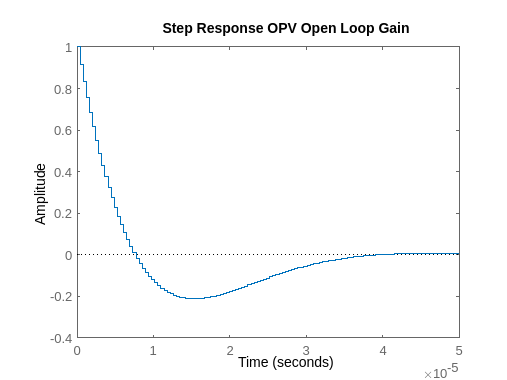

step(1/(1+open_loop_gain));
title('Step Response OPV Open Loop Gain')

How long does it take the loop to respond to an impulse? Here is a rough estimate based on first order system response rise and fall times.

number_symbols = (0.35*Fs)/(w3db_Hz)

number_symbols = 38.4730

response_time = number_symbols*(1/Fs);
fprintf('Response time: %d seconds.\n', response_time)

Response time: 1.565470e-05 seconds.


We can show the locations of the poles. 

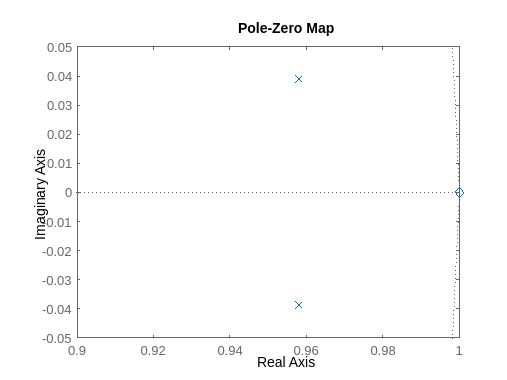

pzmap(1/(1+open_loop_gain));
xlim([0.9 1]);
ylim([-0.05 0.05])

And now we can calculate Kp and Ki.

Kp = tau2/tau1

Kp = 2.8374e-04

Ki = T/tau1

Ki = 1.1468e-05

And now we express the coefficients in our numbering system. We have 16 bits for Kp and 16 bits for Ki, but because the numbers are very small values, we need to represent them with enough resolution. Each bit in the fields of the configuration register is equal to (1/2^effective_register_size). The current effective register size of 12, where we divide the coefficients by (1/4096) to get the decimal value, seems to be a bit too small. 

effective_register_size = 12

effective_register_size = 12

divide_by = power(2,effective_register_size);
fprintf('Divide coeffcient values by one over %d\n', divide_by)

Divide coeffcient values by one over 4096


fprintf('The smallest number we can represent is %d\n', (1/divide_by))

The smallest number we can represent is 2.441406e-04


Kp_decimal_scaled = Kp/(1/(divide_by))

Kp_decimal_scaled = 1.1622

Ki_decimal_scaled = Ki/(1/(divide_by))

Ki_decimal_scaled = 0.0470


Kp_decimal_rounded = round(Kp_decimal_scaled)

Kp_decimal_rounded = 1

Ki_decimal_rounded = round(Ki_decimal_scaled)

Ki_decimal_rounded = 0


Kp_hex = dec2hex(Kp_decimal_rounded)

Kp_hex = '1'

Ki_hex = dec2hex(Ki_decimal_rounded)

Ki_hex = '0'

If we increase the effective register size to a larger number, we can better represent our gain coefficients.

effective_register_size = 16

effective_register_size = 16

divide_by = power(2,effective_register_size);
fprintf('Divide coeffcient values by one over %d\n', divide_by)

Divide coeffcient values by one over 65536


fprintf('The smallest number we can represent is %d\n', (1/divide_by))

The smallest number we can represent is 1.525879e-05


Kp_decimal_scaled = Kp/(1/(divide_by))

Kp_decimal_scaled = 18.5950

Ki_decimal_scaled = Ki/(1/(divide_by))

Ki_decimal_scaled = 0.7516


Kp_decimal_rounded = round(Kp_decimal_scaled)

Kp_decimal_rounded = 19

Ki_decimal_rounded = round(Ki_decimal_scaled)

Ki_decimal_rounded = 1


Kp_hex = dec2hex(Kp_decimal_rounded)

Kp_hex = '13'

Ki_hex = dec2hex(Ki_decimal_rounded)

Ki_hex = '1'

16 bits isn't quite enough resolution. Let's keep going.


effective_register_size = 24

effective_register_size = 24

divide_by = power(2,effective_register_size);
fprintf('Divide coeffcient values by one over %d\n', divide_by)

Divide coeffcient values by one over 16777216


fprintf('The smallest number we can represent is %d\n', (1/divide_by))

The smallest number we can represent is 5.960464e-08


Kp_decimal_scaled = Kp/(1/(divide_by))

Kp_decimal_scaled = 4.7603e+03

Ki_decimal_scaled = Ki/(1/(divide_by))

Ki_decimal_scaled = 192.4030


Kp_decimal_rounded = round(Kp_decimal_scaled)

Kp_decimal_rounded = 4760

Ki_decimal_rounded = round(Ki_decimal_scaled)

Ki_decimal_rounded = 192


Kp_hex = dec2hex(Kp_decimal_rounded)

Kp_hex = '1298'

Ki_hex = dec2hex(Ki_decimal_rounded)

Ki_hex = 'C0'

Is this enough resolution? Let's try 32 bits.


effective_register_size = 32

effective_register_size = 32

divide_by = power(2,effective_register_size);
fprintf('Divide coeffcient values by one over %d\n', divide_by)

Divide coeffcient values by one over 4294967296


fprintf('The smallest number we can represent is %d\n', (1/divide_by))

The smallest number we can represent is 2.328306e-10


Kp_decimal_scaled = Kp/(1/(divide_by))

Kp_decimal_scaled = 1.2186e+06

Ki_decimal_scaled = Ki/(1/(divide_by))

Ki_decimal_scaled = 4.9255e+04


Kp_decimal_rounded = round(Kp_decimal_scaled)

Kp_decimal_rounded = 1218639

Ki_decimal_rounded = round(Ki_decimal_scaled)

Ki_decimal_rounded = 49255


Kp_hex = dec2hex(Kp_decimal_rounded)

Kp_hex = '12984F'

Ki_hex = dec2hex(Ki_decimal_rounded)

Ki_hex = 'C067'

Now that we have the Kp and Ki values, we can now write the transfer function for the PI Controller in discrete-time parallel form.

OPV_pi_tf = pid(Kp, Ki, 'Ts', T, 'Iformula','ForwardEuler')

OPV_pi_tf =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 0.000284, Ki = 1.15e-05, Ts = 4.07e-07
 
Sample time: 4.069e-07 seconds
Discrete-time PI controller in parallel form.



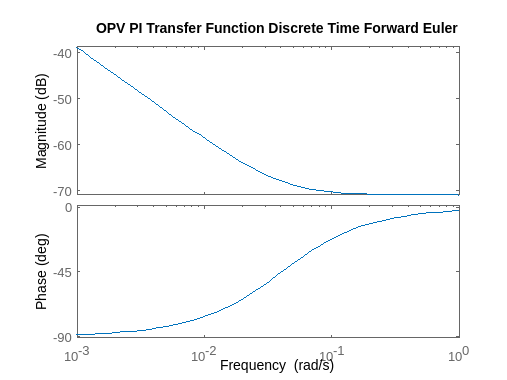

bode(OPV_pi_tf);
title('OPV PI Transfer Function Discrete Time Forward Euler')